## Strategy Estimation for Las Vegas GP 2023

% Tyres available: C3, C4, C5 - The 3 softest in the Pirelli range.
% Race Duration: 50 laps (305.88km total distance)

% Assumption of tyre pace delta per lap: 0.5s between C5 and C4, and 0.5s
% between C4 and C3. With C5 being the fastest.

% Assumption of degradation per lap: Fuel corrected laptime increase
% linearly as tyre wears (linear tyre deg model assumed due to lack 
% of detailed information on compounds)

% Fuel correction assumption for 110kg of fuel to last 50 laps and 0.035s
% laptime gain per 1kg of fuel burn.

% Initial flying lap pace assumed due to lack of race historical data. 

Calculating Fuel Correction Factor

fuelQuantity = 110;  %kg
totalLapNumber = 50; %laps
lapNumber = 1:50;
timePerKg = 0.035;   %seconds

fuelConsumption = fuelQuantity/totalLapNumber;   %kg/lap

fuelCorrectionFactor = fuelConsumption .* timePerKg; %seconds/lap

fuelLapCorrections = fuelCorrectionFactor .* (lapNumber-1);

Defining Tyre Wear Factors

c5Wear =0.155; %s/lap
c4Wear =0.115; %s/lap
c3Wear =0.1; %s/lap

tyreAge = 1:50; %laps

Calculating Tyre Degradation Laptime Impact

c5InitialLaptime = 95;   %seconds
c4InitialLaptime = 95.5; %seconds
c3InitialLaptime = 96;   %seconds

c5TyreDegLaptime = c5InitialLaptime + c5Wear .* (tyreAge-1);
c4TyreDegLaptime = c4InitialLaptime + c4Wear .* (tyreAge-1);
c3TyreDegLaptime = c3InitialLaptime + c3Wear .* (tyreAge-1);

Calculating Tyre and Fuel Effected Laptimes for Full Distance Tyre Model

c5Laptime = c5InitialLaptime + (c5Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);
c4Laptime = c4InitialLaptime + (c4Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);
c3Laptime = c3InitialLaptime + (c3Wear .* (tyreAge-1)) - fuelLapCorrections(lapNumber);

To determine fuel corrected laptimes for individual stints, the following formula is appropriate:

% Fuel_Corrected_Stint_Formula = TyreDegLaptime(tyreAge(1:end_of_stint)) - fuelLapCorrections(lapNumber(stint_start_lap:stint_end_lap))

Defining Average Pit Time Loss

pitTime = 20;  %seconds

Plot Laptimes for Tyre Compounds Over Full Distance. 

This will be our estimated tyre model, from which we can devise strategy configurations and plot their corresponding race times.

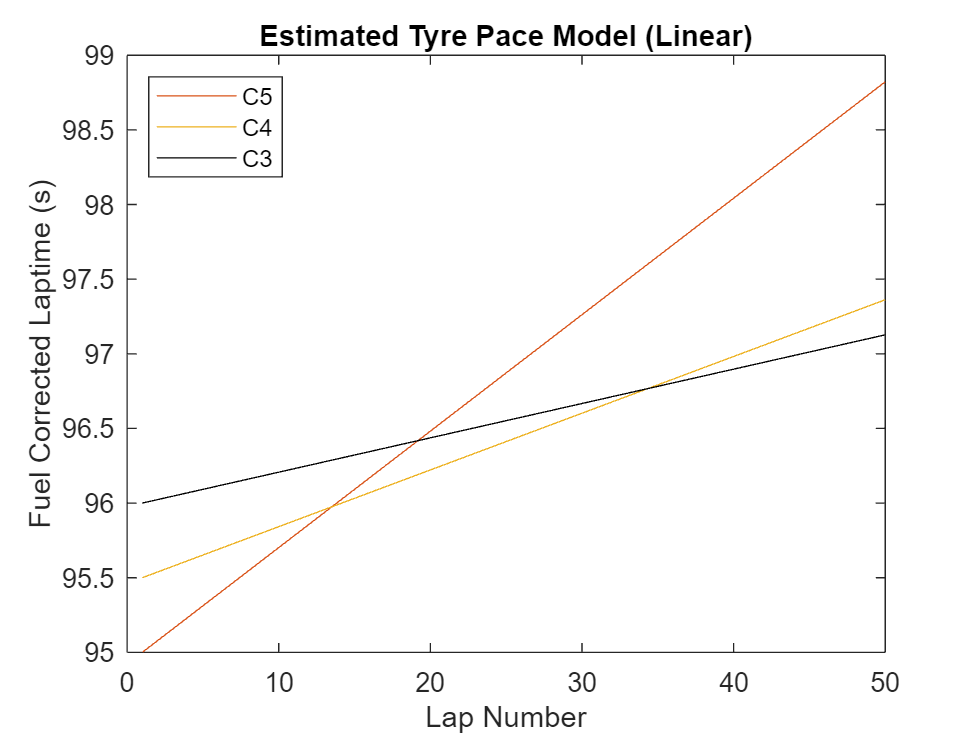

plot(lapNumber,c5Laptime,"Color","#D95319")
hold on
plot(lapNumber,c4Laptime,"Color","#EDB120")
plot(lapNumber,c3Laptime,"Color","#000000")
xlabel("Lap Number")
ylabel("Fuel Corrected Laptime (s)")
title("Estimated Tyre Pace Model (Linear)")
legend(["C5" "C4" "C3"],"Location","northwest")
hold off

Consider a single stop strategy. C5 to C4 (Soft to Medium).

pitLap = 20;

%Fuel Corrected Stints
c5Fuel_Corrected_Stint = c5Laptime(tyreAge(1:pitLap))

c5Fuel_Corrected_Stint =    95.0000   95.0780   95.1560   95.2340   95.3120   95.3900   95.4680   95.5460   95.6240   95.7020   95.7800   95.8580   95.9360   96.0140   96.0920   96.1700   96.2480   96.3260   96.4040   96.4820


c4Fuel_Corrected_Stint = c4TyreDegLaptime(tyreAge(1:(50-pitLap))) - fuelLapCorrections(lapNumber(pitLap+1:50))

c4Fuel_Corrected_Stint =    93.9600   93.9980   94.0360   94.0740   94.1120   94.1500   94.1880   94.2260   94.2640   94.3020   94.3400   94.3780   94.4160   94.4540   94.4920   94.5300   94.5680   94.6060   94.6440   94.6820   94.7200   94.7580   94.7960   94.8340   94.8720   94.9100   94.9480   94.9860   95.0240   95.0620


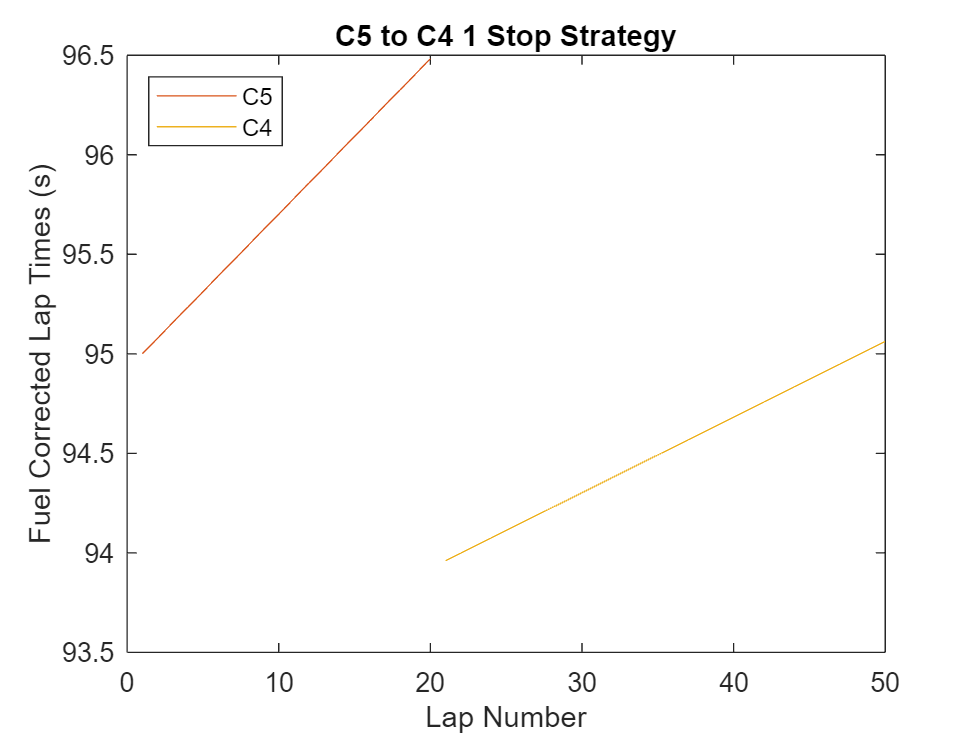


plot(lapNumber(1:pitLap), c5Fuel_Corrected_Stint,"Color","#D95319")
hold on
plot(lapNumber(pitLap+1:50), c4Fuel_Corrected_Stint,"Color","#EDB120")
xlabel("Lap Number")
ylabel("Fuel Corrected Lap Times (s)")
title("C5 to C4 1 Stop Strategy")
legend(["C5" "C4"],"Location","northwest")
hold off

totalRaceTimeC5C4 = sum(c5Fuel_Corrected_Stint) + sum(c4Fuel_Corrected_Stint) + pitTime  %seconds

totalRaceTimeC5C4 = 4.7701e+03

Consider a single stop strategy. C4 to C3 (Medium to Hard).

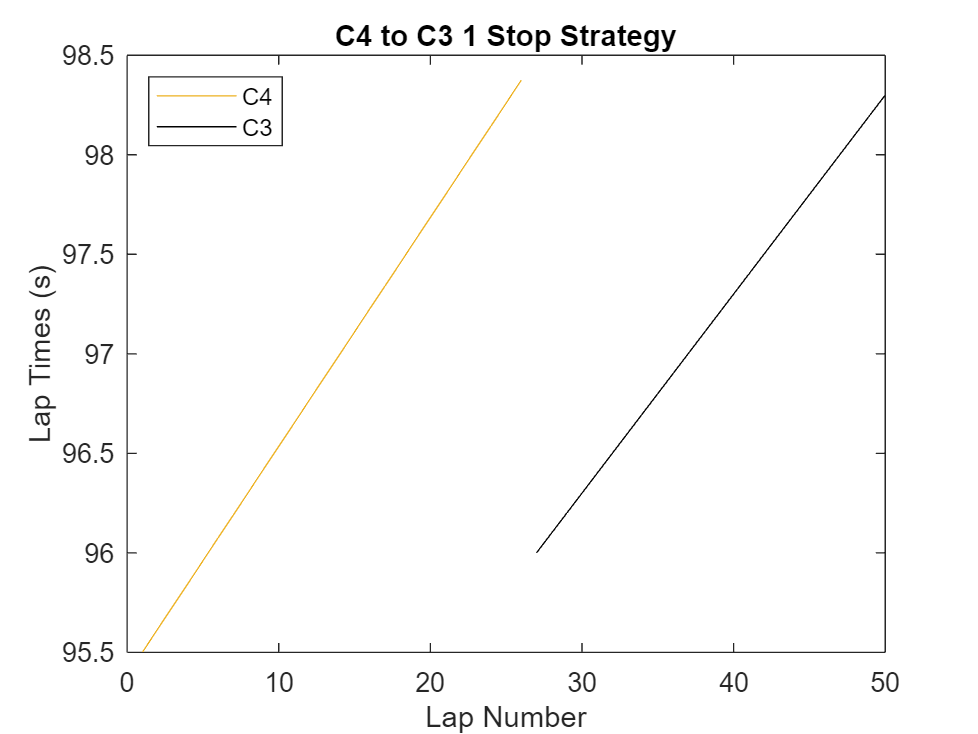

pitLap = 26;

plot(lapNumber(1:pitLap), c4TyreDegLaptime(tyreAge(1:pitLap)),"Color","#EDB120")
hold on
plot(lapNumber(pitLap+1:50), c3TyreDegLaptime(tyreAge(1:(50-pitLap))),"Color","#000000")
xlabel("Lap Number")
ylabel("Lap Times (s)")
title("C4 to C3 1 Stop Strategy")
legend(["C4" "C3"],"Location","northwest")
hold off

totalRaceTimeC4C3 = sum(c4TyreDegLaptime(tyreAge(1:pitLap))) + sum(c3TyreDegLaptime(tyreAge(1:(50-pitLap)))) + pitTime  %seconds

totalRaceTimeC4C3 = 4.8720e+03

Consider a 2 stop strategy. C5, C5, C4 (Soft, Soft, Medium).

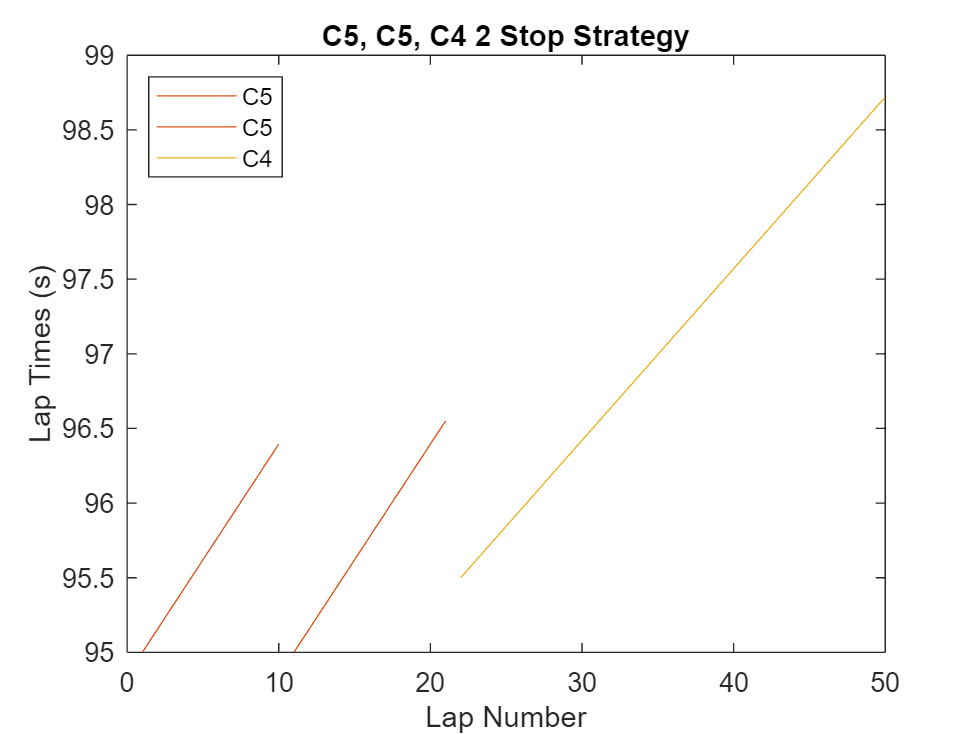

pitLap1 = 10;
pitLap2 = 21;
plot(lapNumber(1:pitLap1), c5TyreDegLaptime(tyreAge(1:pitLap1)),"Color","#D95319")
hold on
plot(lapNumber(pitLap1+1:pitLap2), c5TyreDegLaptime(tyreAge(1:pitLap2-pitLap1)),"Color","#D95319")
plot(lapNumber(pitLap2+1:50), c4TyreDegLaptime(tyreAge(1:(50-pitLap2))),"Color","#EDB120")
xlabel("Lap Number")
ylabel("Lap Times (s)")
title("C5, C5, C4 2 Stop Strategy")
legend(["C5" "C5" "C4"],"Location","northwest")
hold off

totalRaceTimeC5C5C4 = sum(c5TyreDegLaptime(tyreAge(1:pitLap1))) + sum(c5TyreDegLaptime(tyreAge(pitLap1:pitLap2))) + sum(c4TyreDegLaptime(tyreAge(1:(50-pitLap2)))) + (2.*pitTime)  %seconds

totalRaceTimeC5C5C4 = 4.9801e+03